# 1 Propagation sans altérations

### 1.1 Synthèse des signaux

    On initialise les differentes variables.

clear variables;
close all;

A = 1;
Fs = 1000;
f_0 = 7;
T_0 = 1/f_0;
T = 5 * T_0;
D = 3 * T;
N = D.*Fs;

    On calcule les fonctions puis on les affiche.

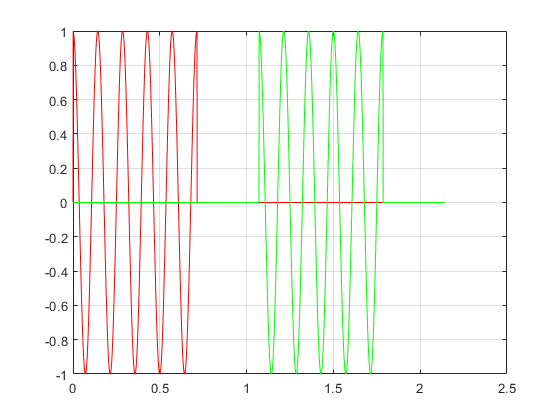

t = linspace(0,D,N+1);
x_t = A*cos(2*pi*f_0*t).*porte(t-D/2,D);
y_t = A*cos(2*pi*f_0*(t-1.5*T)).*porte(t-2*T,T);

plot(t,x_t,'r'); hold on; plot(t,y_t,'g'); grid on; hold off;

### 1.2 Fonction d'inter-corrélation

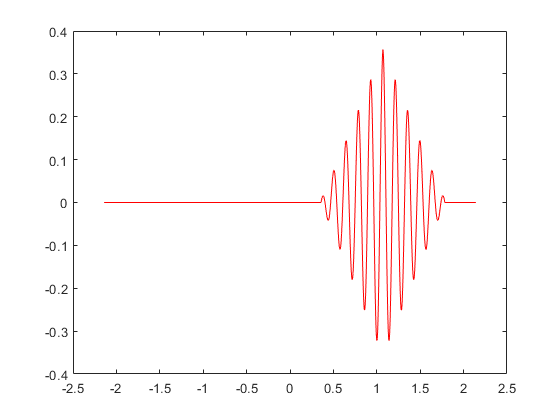

[gamma,k]=xcorr(y_t,x_t);
to=k/Fs;
plot(to,gamma/Fs,'r');

"k" représente le retard. Elle est relié au retard tau par la relation : 

k = arg max{gamma(tau-k))

forme good -> beau losange

milieur good

max amplitude good

5/7/2 = 0.357

Valeur trouvé => 0.357

### 2 Propagation à travers un média bruité

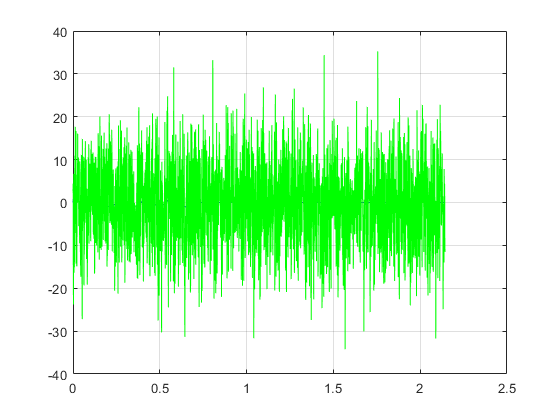

sigma = 10;
z_t = y_t + sigma*randn(size(y_t));
plot(t,x_t,'b'); hold on; plot(t,z_t,'g'); grid on; hold off;


[gammaz,k]=xcorr(z_t,x_t);
subplot(211); plot(to,gammaz/Fs,'r');
subplot(212); plot(to,gamma/Fs,'r');


### 3 Réflexion sur une cible en mouvement

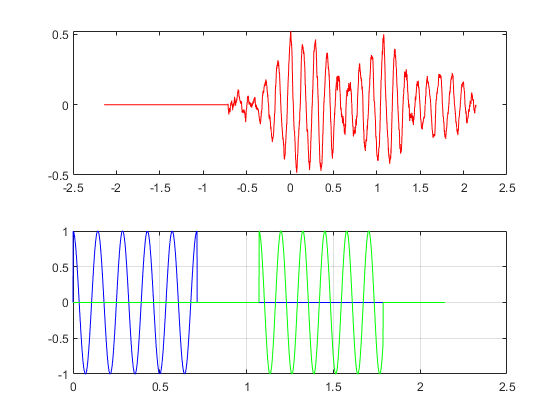

w_t = cos(2*pi*(f_0*1.13)*(t-1.5*T)).*porte((t-2*T),T);
plot(t,x_t,'b'); hold on; plot(t,w_t,'g'); grid on; hold off;